# Track and Follow an Object

In this example, you explore autonomous behavior that incorporates the Kinect® camera. This algorithm involves the TurtleBot® looking for a blue ball and then staying at a fixed distance from the ball. You incorporate safety features, such as bump and cliff sensing.

*Running this example requires the Image Processing Toolbox™.*

Prerequisites: [Communicate with the TurtleBot](docid:ros_ug.mw_22539b8a-6acf-47a9-bac1-bd7ad3731d62), [Explore Basic Behavior of the TurtleBot](docid:ros_ug.mw_953f208b-5f53-47e8-bcfd-cb43f322e5ff), [Control the TurtleBot with Teleoperation](docid:ros_ug.mw_fb0a866f-3aed-442c-91b6-e473a164cdec), [Obstacle Avoidance Using TurtleBot](docid:ros_ug.mw_d2313296-658d-48d7-b005-880daa08ce9c)

## Hardware Support Package for TurtleBot

This example gives an overview of working with a TurtleBot using its native ROS interface. The **ROS Toolbox™ Support Package for TurtleBot based Robots** provides a more streamlined interface to TurtleBot. It allows you to:

Acquire sensor data and send control commands without explicitly calling ROS commands

Communicate transparently with a simulated robot in Gazebo or with a physical TurtleBot

To install the support package, open **Add-Ons > Get Hardware Support Packages** on the MATLAB® **Home** tab and select **ROS Toolbox™ Support Package for TurtleBot based Robots**. Alternatively, use the [`roboticsAddons`](docid:robotics_ref.bu5jj8h) command.

## Connect to the TurtleBot

Make sure you have a TurtleBot running either in simulation through Gazebo® or on real hardware. Refer to  [Get Started with Gazebo and a Simulated TurtleBot](docid:ros_ug.mw_9c45a664-ab3d-48a5-a65a-52913b8532b5) or [Get Started with a Real TurtleBot](docid:ros_ug.mw_c9b2d3c3-0e9c-4222-8294-1453212e9813) for the startup procedure. If you are using hardware, find a blue ball to use for tracking. If you are using Gazebo®, the blue ball must be in the world in front of the robot (make sure that you are using **Gazebo Office** world).

Initialize ROS. Connect to the TurtleBot by replacing `ipaddress` with the IP address of the TurtleBot

ipaddress = "192.168.178.133";
rosinit(ipaddress,11311)

Make sure that you have started the Kinect camera if you are working with real TurtleBot hardware. The command to start the camera is:  

You must enter this in a terminal on the TurtleBot.

Create subscribers for the color camera, the cliff sensor, and the bumper sensor. Create publishers for emitting sound and for controlling the robot velocity messages. Communicate using messages in structure format for better performance.

handles.colorImgSub = exampleHelperTurtleBotEnableColorCamera;
useHardware = exampleHelperTurtleBotIsPhysicalRobot;
if useHardware
    handles.cliffSub = rossubscriber("/mobile_base/events/cliff",...
        "BufferSize",5,"DataFormat","struct");
    handles.bumpSub = rossubscriber("/mobile_base/sensors/bumper_pointcloud",...
        "BufferSize",5,"DataFormat","struct");
    handles.soundPub = rospublisher("/mobile_base/commands/sound", "kobuki_msgs/Sound",...
        "DataFormat","struct");
    handles.velPub = rospublisher("/mobile_base/commands/velocity",...
        "DataFormat","struct");
else
    % Cliff sensor, bumper sensor and sound emitter are only present in
    % real TurtleBot hardware
    handles.cliffSub = [];
    handles.bumpSub = [];
    handles.soundPub = [];
    handles.velPub = rospublisher("/cmd_vel","DataFormat","struct");
end

## Tune the Blue Ball Detection

Set the parameters for image filtering. Add them to a data structure that will be used in the algorithm.

blueBallParams.blueMax = 120;  % Maximum permissible deviation from pure blue
blueBallParams.darkMin = 30;   % Minimum acceptable darkness value

Try to visualize the ball to make sure that the ball-finding parameters can locate it. Run the `exampleHelperTurtleBotFindBlueBall` function to see if a circle is found. If so, `c` and `m` are assigned values. `ball` is a binary image created by applying blueness and darkness filters on the image. View `ball` to see if the blue ball was properly isolated:

latestImg = rosReadImage(handles.colorImgSub.LatestMessage);
[c,~,ball] = exampleHelperTurtleBotFindBlueBall(latestImg,blueBallParams,useHardware);

Use this example helper to display the real and binary image in a figure and plot a red plus at the center of the ball. 

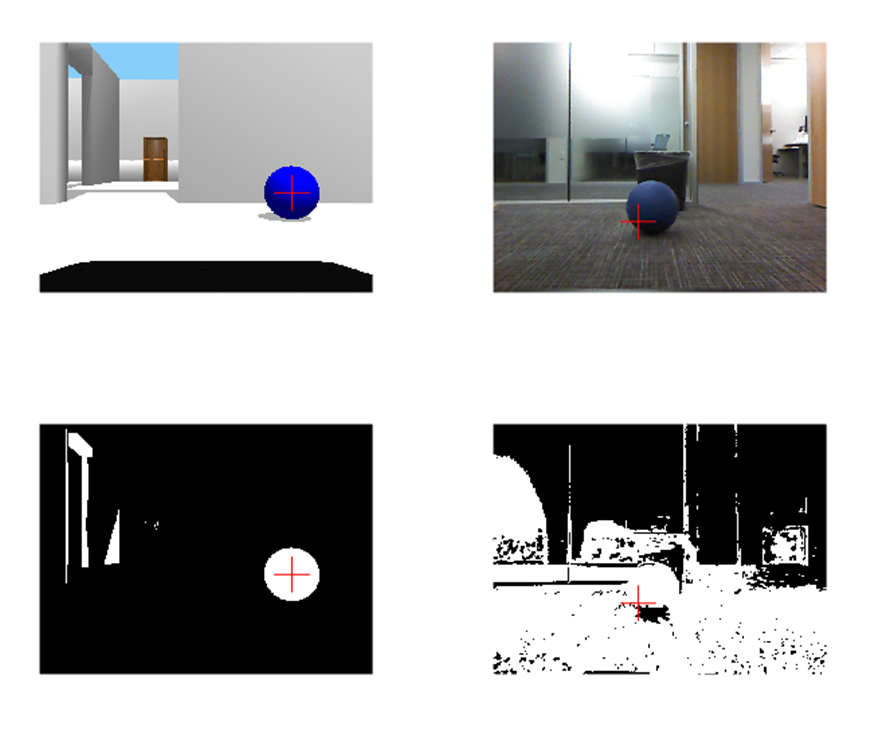If the ball is not found, try increasing or decreasing `blueBallParams.blueMax` and `blueBallParams.darkMin`. View the plot again until the ball is found. This method is a good way to fine tune the ball-finding algorithm before using the controller. 

In Gazebo, the parameters used might not find the ball, because the threshold values are too generous. The Gazebo image (left figures) includes parts of the wall and other objects in the white space. The real image (right figures) looks very saturated with white. Try changing the parameters so that they are more restrictive:

blueBallParams.blueMax = 200; % Maximum permissible deviation from pure blue
blueBallParams.darkMin = 220; % Minimum acceptable darkness value
latestImg = rosReadImage(handles.colorImgSub.LatestMessage);
[c,~,ball] = exampleHelperTurtleBotFindBlueBall(latestImg,blueBallParams,useHardware);

Use this example helper to display the figures.

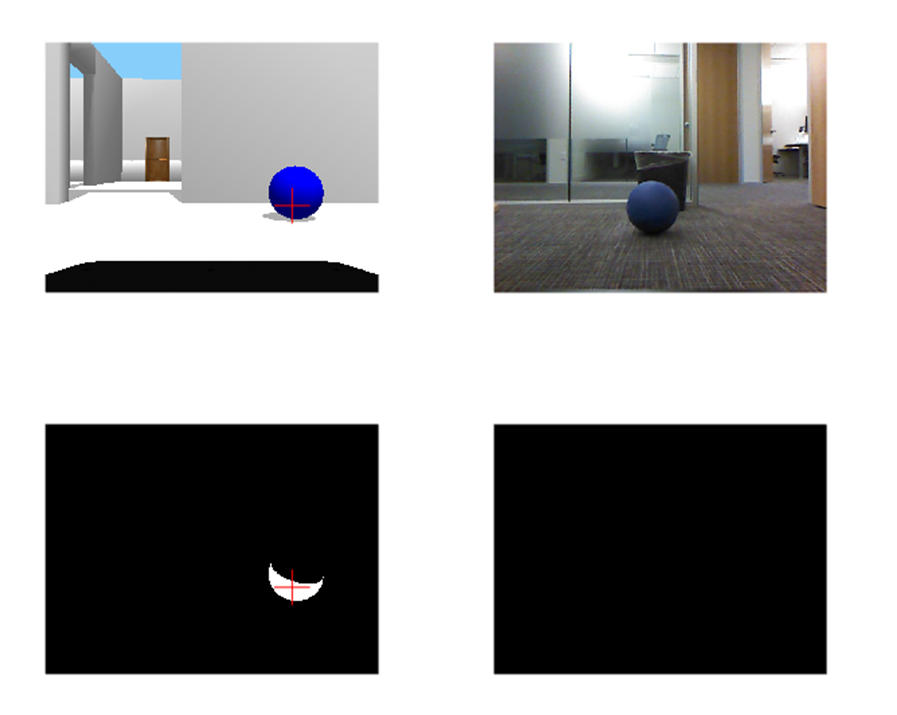

Now the parameters are too restrictive. Part of the ball does not even show up in the Gazebo image, and you see nothing in the real image. If you tune the parameters further you can find a middle ground. In Gazebo, the following parameters should work well. With hardware, ambient lighting might require you to spend more time fine tuning the parameters.

  blueBallParams.blueMax = 30; % Maximum permissible deviation from pure blue
  blueBallParams.darkMin = 90; % Minimum acceptable darkness value
  latestImg = rosReadImage(handles.colorImgSub.LatestMessage);
  [c,~,ball] = exampleHelperTurtleBotFindBlueBall(latestImg,blueBallParams, useHardware);

Use this example helper to display the figures. 

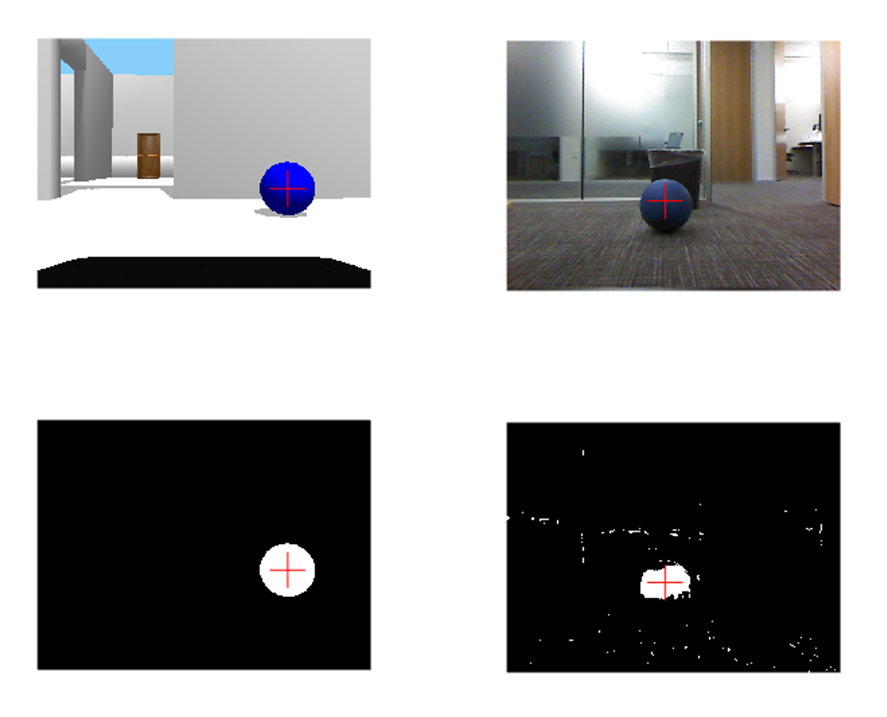

Tuning the color thresholds is challenging when compared to tuning them in a simulated environment like Gazebo.

After you have fine-tuned the parameters, add them to the `handles` object, which will be used by the ball tracking algorithm.

  handles.params = blueBallParams;

## Test Fixed-Distance Controller

Set controller gains for the TurtleBot. The TurtleBot uses a PID controller to stay at a constant distance from the ball.

The first set of controller gains is good for a TurtleBot in Gazebo. The second set is good for a TurtleBot in real hardware. Adjust the gains as you see fit.

Here is a compact way to assign the struct values.

*Effective gains for Gazebo simulation:*

  gains.lin = struct("pgain",1/100,"dgain",1/100,"igain",0,"maxwindup",0,"setpoint",0.65);
  gains.ang = struct("pgain",1/400,"dgain",1/500,"igain",0,"maxwindup",0,"setpoint",0.5);
 

*Effective gains for TurtleBot hardware:*

Make sure to add the `gains` struct to the `handles` variable.

handles.gains = gains;

Define a timer to execute the ball tracking behavior through the callback. Define the stop function to shut down ROS. Include the handles in the callback function for the timer:

timer2 = timer("TimerFcn",{@exampleHelperTurtleBotTrackingTimer,handles,useHardware},"Period",0.1,"ExecutionMode","fixedSpacing");
timer2.StopFcn = {@exampleHelperTurtleBotStopCallback};

Start the timer using the following command. You see the TurtleBot begin to move around the world, searching for the ball. When it finds it in the Kinect image, the robot will use the controller to stay at a fixed distance.

start(timer2);
pause(1);

The bump sensor does not activate in simulation, so the TurtleBot might not recover when it hits a wall.

If you want to move the blue ball around, use the following commands to apply a force:    

If you want to further explore Gazebo control of the simulation refer to [Add, Build, and Remove Objects in Gazebo](docid:ros_ug.mw_aefba829-05e2-4e06-9209-900daf7fb987).

## Stop Robot Motion

To stop the timer and autonomous behavior, use the following command:

stop(timer2);

If the timer is cleared from the workspace before it is stopped, you must delete it another way. To stop all timers (even timers in the background) execute the following command:

delete(timerfindall)

Clear the workspace of publishers, subscribers, and other ROS related objects when you are finished with them

clear

## More Information

*NOTE: Code in this section is not for MATLAB command line execution*

In this example, the organization of supporting files allows you great flexibility in customizing and re-purposing the code. You can alter the ball-finding parameters and the controller gains by changing values in the `handles` struct. This example incorporates a [`timer`](docid:matlab_ref.btwomz1-1) that manages all aspects of the control algorithm. This timer is the `exampleHelperTurtleBotTrackingTimer`. This timer has Name-Value pairs of `Period` and `ExecutionMode` that are set to determine how often the timer callback is called. Additionally, the stop callback is used. You can incorporate additional callback functions if you want.

The handles passed into the timer include `params` for ball-finding and `gains` for the controller.

The structure of `exampleHelperTurtleBotTrackingTimer` is simple. It is a basic state machine with some initialization steps. The initialization function determines which tracking algorithm and which controller to use when not in a cliff or bumper recovery state. The function is:

In this example the tracking function is  `exampleHelperTurtleBotFindBlueBall` and the controller is `exampleHelperTurtleBotPointController` You can replace this function and controller with any user-defined functions that have the same input and output argument structure. The input arguments for `exampleHelperTurtleBotFindBlueBall` are a color image and a struct of ball-finding parameters. The output arguments are a center, magnitude, and binary image of the sought object. The input arguments for `exampleHelperTurtleBotPointController` are object center, magnitude (though magnitude is not used in the example), image size, and controller gains (a struct). The output arguments are linear and angular velocities.

The basic state machine used in `exampleHelperTurtleBotTrackingTimer` is:

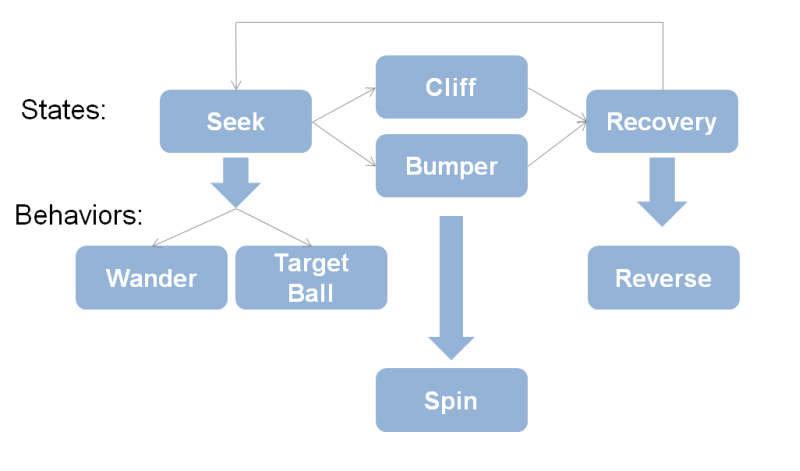

You can add or remove cases from the state machine. If you want to change the state names, use the `ExampleHelperTurtleBotStates` class.

The ball-finding algorithm is modular and alterable. It uses two image filters (one on darkness and one on blueness) masked together to isolate the blue ball. You can change the masks to find a red or green ball instead. If you want to explore other forms of shape-tracking, the basic workflow remains the same. 

The blue channel is isolated (with some scaling factors) and a threshold is applied to produce a binary image mask.

These commands isolate the inverse of the blue (with different scaling) and emphasize darkness. A threshold is applied.

Mask the two binary images together to isolate the dark blue ball.

The constants and scaling factors on the image are user-determined to isolate a specific color. You can experiment with various combinations.

You can also find contiguous regions in the filtered image using `regionprops`, which is part of the Image Processing Toolbox.

There are additional steps to find the ball from this region, which you can find in `exampleHelperTurtleBotFindBlueBall`.

The `exampleHelperTurtleBotPointController` function uses the `ExampleHelperPIDControl` class to keep a specified point (in this case the location of the center of the ball) at an exact location within the image.

The modularity and flexibility of the example code allows you to experiment with your own algorithms and functions.

*Copyright 2014-2021 The MathWorks, Inc.*